# **PORTFOLIO THEORY (STA4028Z)**

# Data Wrangling and Optimization in MATLAB

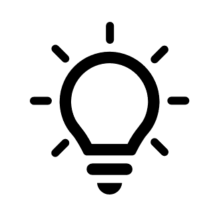 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/university-of-cape-town-31484474.html)!

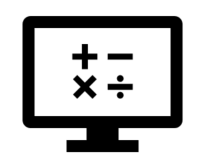 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

**Required Toolboxes:** 

- Financial Toolbox

- Optimization Toolbox

**Recommended Lecture Readings:** 

- Carmona, R., (2014) Statistical Analysis of Financial Data in R, Springer

**Recommended Course Reading:** 

- Elton, E., Gruber, M., Brown, S., and Goetzmann, W., (2014), Modern Portfolio Theory and Investment Analysis, 9-th edition, Wiley [Chapters 13, 17, 26, 28] 

- Lee, W., (2000)Theory and Methodology of Tactical Asset Allocation [Chapter 2, 3, 7] 

- Prigent, P-L., (2007), Portfolio Optimization and Performance analysis. Chapman & Hall [Chapter 1, ...] 

- Ross, S., (2005), Neoclassical Finance, Princeton Press [Chapter 1]

#### Markdown

### Rules of Engagement

- You are strongly encouraged to **workshop and discuss assignment outputs**, graphs, tables and algorithms in order to refine your thinking about assignment solutions.

- **There is to be no code sharing**. Duplicate code will be treated as plagiarism, and as such, intellectual property theft. 

-  All MATLAB code is to be included in the appendix of your assignment submission marked up in the appropriate LaTeX environment. Where appropriate referenced by code pattern in the body of the assignment.

- All equations used should be presented and discussed using the correct TeX markup. 

- MATLAB code executed within the document is to be suppressed where appropriate. The output is what is of interest in the body of the assignment text.

#### Script file description

Load the Tactical Asset Allocation data from EXCEL 

-  ICB Industrial Level Indices 

-  ALBI (All Bond Index (ALBI) Total Return Index (TRI) Data) 

-  Money Market Data: JIBAR and STEFI TRI 

-  Various Indices: JSE Growth, JSE Value, JSE ALSI, JSE SRI 

 Situation: Load data from *.csv file and convert into timeSeries 

To open Excel spreadsheet: Navigate to the folder in the current folder, right click on spreadsheet and choose "Open Outside MATLAB"

#### Clear environment and remove all plots

clc % clears the command window
close all %removes all figures
clear % clears the workspace

####  Paths

Use your user path and folders to specify the correct path using absolute paths

% % use your default user path to create the filename and path
% fileName = "PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx"
% fileName = fullfile(userpath,'\STA4028Z\Data\',fileName)

### Loading the data from Excel spreadsheets 

Load the dataset by sheet using [readtimetable](https://www.mathworks.com/help/matlab/ref/readtimetable.html). MATLAB has many functions to read in data in the format you would like to use it in. See [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html)`,` [`readmatrix`](https://www.mathworks.com/help/matlab/ref/readmatrix.html)`, `[`readvars`](https://www.mathworks.com/help/matlab/ref/readvars.html)`, `[`readcell`](https://www.mathworks.com/help/matlab/ref/readcell.html)`.`

Timetable is a type of table that associates a time with each row. Like table, the timetable data type can store column-oriented data variables that have the same number of rows. All table functions work with timetables. In addition, timetables provide time-specific functions to align, combine, and perform calculations with one or more timetables. For more information, see [Create Timetables](https://www.mathworks.com/help/matlab/matlab_prog/create-timetables.html) or watch [Managing Time-Stamped Tabular Data with Timetables](https://www.mathworks.com/videos/managing-time-stamped-tabular-data-with-timetable-120888.html).

The loaded Excel sheets will be saved in a [cell array](https://www.mathworks.com/help/matlab/cell-arrays.html). A cell array is a data type with indexed data containers called cells. Each cell can contain any type of data. Cell arrays commonly contain pieces of text, combinations of text and numbers from spreadsheets or text files, or numeric arrays of different sizes.

excelSheetNames = sheetnames("C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx");

%Preallocate cell array before looping
data{numel(excelSheetNames)} = [];

%Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
data{sheet} = readtimetable("PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx",'Sheet',excelSheetNames{sheet},VariableNamingRule='preserve', VariableNamesRange ='A1', VariableDescriptionsRange = 'A2',Range='A5');
end

#### Keep only the specified list of Tickers

Find Tickers in the column names and keep the TRI only of sheets JSE ICB 0500 Indices and JSE Various Indices.

[strncmp](https://www.mathworks.com/help/matlab/ref/strncmp.html) is one of the text comparison functions that can be used. Read more [here](https://www.mathworks.com/help/matlab/matlab_prog/string-comparisons.html).

variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'ALBI', 'J203', 'J500', variableTickers{:}};

for i = 1:numel(data)
    % 1. Keep TRI only in sheets 3 and 4
    if i == 3
       allVarTable = data{i}; 
       TRITable = allVarTable(:,(3:3:27));
       data{i} = TRITable;
    elseif i == 4
       allVarTable = data{i};
       allVarTable = removevars(allVarTable,["SOURCE68779","Var2"]);
       TRITable = allVarTable(:,(4:4:19));
       data{i} = TRITable;
    end
    % 2. Find Tickers in column names,
        % get the table properties
        opts = data{i}.Properties;
        % Preallocate array for matching
        variableMatch = zeros(size(opts.VariableNames));   
        % Do a string comparison to find tickers
        if i == 2 %Match 8 letters for STEFI to prevent unwanted variables
            for k = 1:numel(entities)
                variableMatch(strncmp(opts.VariableNames,entities{k},8)) = k;
            end
        else
            for k = 1:numel(entities)
                variableMatch(strncmp(opts.VariableNames,entities{k},4)) = k;
            end
        end
        % Index for unwanted tickers
        idx = find(variableMatch==0);
        %Remove unwanted tickers from the data
        tickersToBeRemoved = opts.VariableNames(idx);
        data{i} = removevars(data{i}, tickersToBeRemoved);
        % clean up the remaining column names 
        hasColon = contains(data{i}.Properties.VariableNames, ':');     
        data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon),':');
end

#### Clean and convert into a single timetable

Combine all four tables into one using synchronize. 

The synchronize function collects the variables from all input timetables, synchronizes them to a common time vector, and returns the result as a single timetable. The effect is similar to a horizontal concatenation, though the input timetables can have different row times. When the synchronize function synchronizes timetable variables to different times, it also resamples or aggregates the data in the variables using a method that you specify.

allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','J203'}, {'STEFI','ALSI'});

#### Resample and Visualise 

Convert from Daily Sampled Data to Monthly Sampled Data. 

% Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable);

Remove dates in the timetable where data is not recorded, i.e holidays,weekends once you are at the required sampling frequency. First, visualise where there is missing data (e.g. a NaN).

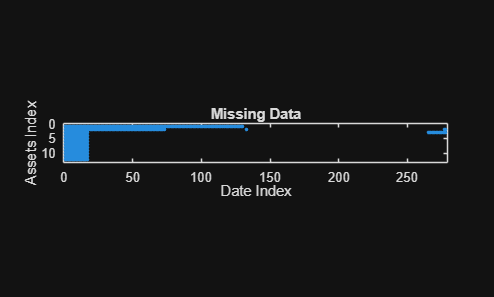

spy(transpose(isnan(table2array(allDataTable))));
ylabel("Assets Index")
xlabel("Date Index")
title("Missing Data")

The recording of ALBI and STEFI indices starts a lot later than the other indices and removing all missing data would erase any data recorded prior. There are also assets which delisted or were discontinued and hence they no-longer have recorded data at the end of the dataset. We could fill the missing data with the last measure data set using the prices. There returns would then become zero moving forward.    

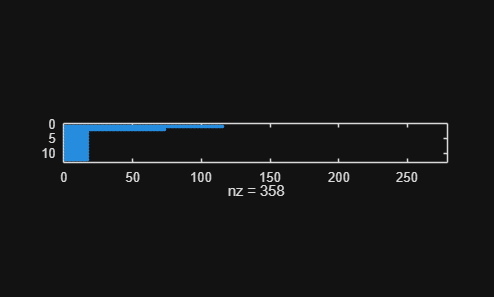

% we are going to use zero-order hold (the missing price is the last price)
allDataTableFilled = fillmissing(allDataTable,'previous');
spy(transpose(isnan(table2array(allDataTableFilled))))

Here we want to find that data set where all the asset are populated sequentially. Having a single missing data point is okay but more than two in a sequence is a problem. We can find a variable with the least nans and use it as a proxy to remove the missing data from the beginning of the dataset.

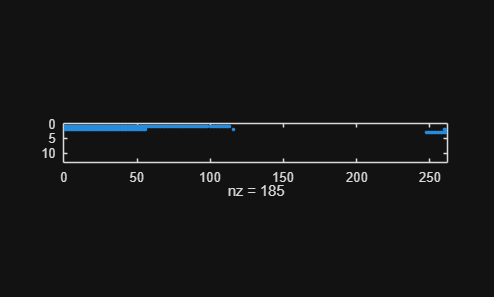

[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(allDataTable))))

The problem is that we see that there is still missing data in the first 3 asset, and for the 3rd asset at the end too. So we can try remove all the missing data in the early part of the dataset. 

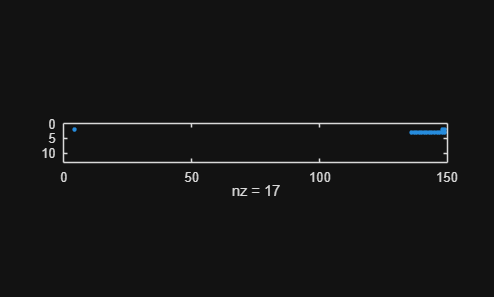

[countNans,idx] = max(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(allDataTable))))

We can remove all the data at the end of the data set

[countNans,idx] = max(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy);

We can now fill in the missing data points

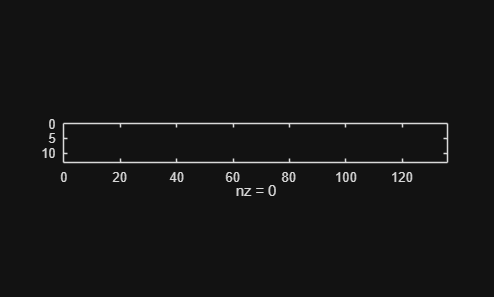

allDataTableFilled = fillmissing(allDataTable,'previous');
spy(transpose(isnan(table2array(allDataTableFilled))))

We can now plot these as times series plots

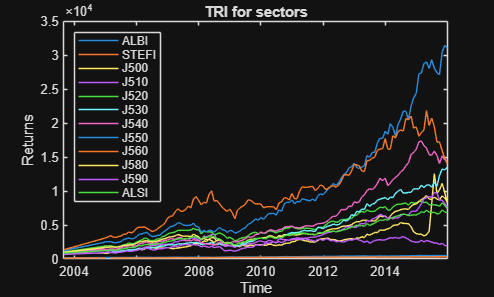


% Visualise the data on a single plot
%plot the timeseries
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
xlabel("Time")
title("TRI for sectors")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="northwest")

#### Compute returns

Remove rows and columns with missing data but ensure that the data is uniformly sampled

% compute the daily geometric returns and omit nan (not a number)
allDataTable = rmmissing(allDataTable);

Compute returns Simple returns (rather than Continous returns)


$$R_t = \frac{P_t-P_{t-1}}{P_{t-1}} $$


% allDataReturnsTable = tick2ret(allDataTable,'Method','continuous');
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple');

#### Visualise the Index and Return data

Plot two plots on the same figure 

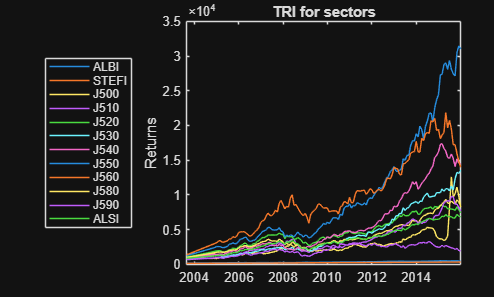

% Top plot
%plot the timeseries
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
title("TRI for sectors")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="westoutside")

% Bottom plot
nexttile

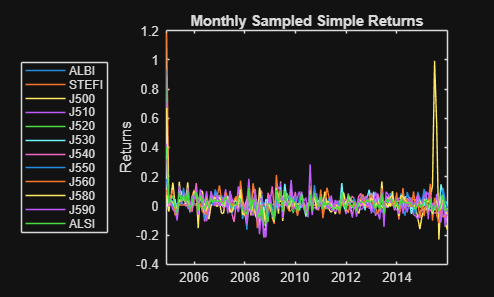

%plot the timeseries
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="westoutside")

#### Save your pre-processed data

The workspace is not maintained across sessions of MATLAB. When you quit MATLAB, the workspace clears. However, you can save any or all the variables in the current workspace to a MAT-file (`.mat`). You can then reuse the workspace variables later during the current MATLAB session or during another session by loading the saved MAT-file.

There are several ways to save workspace variables interactively:

- To save all workspace variables to a MAT-file, on the **Home** tab, in the **Variable** section, click **Save Workspace**.

- To save a subset of your workspace variables to a MAT-file, select the variables in the Workspace browser, right-click, and then select **Save As**. You also can drag the selected variables from the Workspace browser to the Current Folder browser.

- To save variables to a MATLAB script, click the **Save Workspace** button or select the **Save As** option, and in the **Save As** window, set the **Save as type** option to **MATLAB Script**. Variables that cannot be saved to a script are saved to a MAT-file with the same name as that of the script.

You also can save workspace variables programmatically using the [`save`](https://www.mathworks.com/help/matlab/ref/save.html) function. 

save("PortfolioTheory.mat",'allDataTable','allDataReturnsTable')

Read more about saving options [here](https://www.mathworks.com/help/matlab/ref/save.html).

### Load pre-processed data

#### Clear environment and remove all plots

clc % clears the command window
close all % removes all figures
clear % clears the workspace

Load previously prepared data

load('PortfolioTheory.mat')

Tickers to be considered 

tickers = {'J510','J550'};

####  Manage Missing Data

Checking for missing data

isnan(allDataReturnsTable{:,:})

ans = 133×12 logical array
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0


Compute the Geometric mean 

- without correcting for missing data (NAN)

portfolioMean = mean(allDataReturnsTable{:,:});  
portfolioStandardDev = std(allDataReturnsTable{:,:});

         2. include the missing data (NAN)

portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');

We will remove all the rows with missing data

allDataReturnsTable = rmmissing(allDataReturnsTable)

allDataReturnsTable = 133×12 timetable
       Time           ALBI         STEFI        J500          J510         J520          J530          J540         J550          J560          J580         J590          ALSI   
    ___________    __________    _________    _________    __________    _________    __________    __________    _________    __________    __________    _________    __________

    30-Nov-2004       0.18412      0.10833     0.072305       0.42662      0.80346       0.36271       0.71079      0.93438        1.1839      

#### Different kinds of returns when considering compounding and means

We consider three different type of returns and there compunding. First, continous time returns for prices at time t given by $P_t$ 

prc = allDataTable.ALBI;

The price relatives from time $t-1$ to $t$ are $x_t$ 


$$x_t = \frac{P_t}{P_{t-1}}$$
 

The returns $R_t$ (Simple) are then


$$R_t = \frac{P_t- P_{t-1}}{P_{t-1}} = x_t-1$$


The continous returns are $\mu_t$ (Continous)


$$\mu_t = \ln(P_r)-\ln(P_{t-1}) \iff P_t = e^{ \mu_t} P_{t-1} \iff x_t = e^{\mu_t}
$$


This is mathematically useful because it implies that: $P_t = P_0 e^{\mu_t t}$ given an initial price $P_0$.

It is computational convenient becuase returns can be efficientily computed over vectors

mut = diff(log(prc))

mut =     0.1690
    0.0301
    0.0341
   -0.0374
    0.0202
   -0.0010
    0.0265
    0.0096
    0.0006
    0.0008
    0.0063
    0.0234
    0.0195
    0.0096
    0.0077


The arithmetic average of this gives the mean continous returns: $\bar \mu = \frac{1}{n} \sum_{t=1}^n \mu_t$

mu =mean(mut)

mu = 0.0074

Geometric returns are geometrically compounding over discrete time-intervals for times $t=0,1,2,\ldots,t,\ldots,n$ where there are $n+1$ prices and $n$ returns:


$$(R_1+1)(R_2+1) \ldots (R_t+1) \ldots (R_{n}+1) = \frac{P_1}{P_{0}}  \frac{P_2}{P_{1}}  \ldots \frac{P_t}{P_{t-1}}   \ldots \frac{P_n}{P_{n-1}} = \frac{P_n}{P_0}  
  $$


R = (prc(2:end)./prc(1:end-1))-1

R =     0.1841
    0.0306
    0.0347
   -0.0367
    0.0204
   -0.0010
    0.0269
    0.0096
    0.0006
    0.0008
    0.0063
    0.0237
    0.0197
    0.0096
    0.0078


The mean geometric returns are: $\mu_G =  \left( {\prod_{t=1}^n x_t} \right)^\frac{1}{n} -1= \left( {\prod_{t=1}^n (R_t+1)} \right)^\frac{1}{n} -1$ 

muG = exp(mean(log(R+1)))-1

muG = 0.0074

The mean arithmetic returns are: $\mu_A = \frac{1}{n} \sum_{t=1}^n R_t$

muA = mean(R)

muA = 0.0077

These are not the same. Note that because $\mu = \ln(\mu_G+1)$over the entire period we have

prc(1) * exp((length(prc)-1)*mu)

ans = 462.0710

prc(1) * (muG+1)^(length(prc)-1)

ans = 462.0710

prc(end)

ans = 462.0710

We will typically use geometric returns compound monthly because we will hold the portfolio for a single month. These will be annualised when presented i.e. NACM (Nominally Annualised Compounded Monthly) . This can be managed by a portfolio object, however we should make sure that the returns being used are those correct for the use case. Not all portfolio optimisations use monthly geometrically compounded returns. For example, when modelling a long-short hedge fund we will use arithmetically linked returns, and arithmetic averaging (because we will assume the fund has fixed leverage through multiple rebalances), while for a mutual (pension) fund we will using geometric compounding to link the returns across the months, weeks or days. Another example is when holdinng a balanced fund from futures close-out to future close-out and then only rebalancing every 3 months, the returns should be quarterly returns, then are then compounded 4 times over a year to get the appropriate annual returns.  If the continous-time returns $\mu_t$ are Gaussian then the prices will be log-normally distributed. 

#### Create a Portfolio Object

When creating software applications, it is important to organize the various building blocks of your software into related groups.Object-oriented programming (OOP) allows you to group the solver’s configuration parameters (properties) with its functions (methods) into a single definition, or* class*. Everything a user will need to properly execute this solver is defined in this class.

An object is an instance of a class. When a program executes, the object is created based on its class definition and behaves in the way defined by the class. The properties of an object represent its state, and its methods represent all the actions a user may perform. In this way, a code author can easily group all the related data and functions for a software system and a user can easily find and use all the capabilities the code author has developed.

Learn more about OOP:

- [Object-Oriented Programming in MATLAB](https://www.mathworks.com/products/matlab/object-oriented-programming.html)

- [Working with Objects in MATLAB](https://www.mathworks.com/help/matlab/matlab_oop/working-with-objects-in-matlab.html)

- [MATLAB self-paced OOP onramp](https://matlabacademy.mathworks.com/details/object-oriented-programming-onramp/oroop)

The `Portfolio` object implements mean-variance portfolio optimization. Every property and function of the `Portfolio` object is public, although some properties and functions are hidden. See [`Portfolio`](https://www.mathworks.com/help/finance/portfolio.html) for the properties and functions of the `Portfolio` object. 

First create a "standard" `Portfolio` object with [Portfolio](docid:finance_ug.buk6uyz-1) to incorporate the list of assets.

q = Portfolio('AssetList',allDataTable.Properties.VariableNames)

q =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: []
                     AssetMean: []
                    AssetCovar: []
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 12
                     AssetList: {'ALBI'  'STEFI'  'J500'  'J510'  'J520'  'J530'  'J540'  'J550'  'J560'  'J580'  'J590'  'ALSI'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: []
                    UpperBound: []
                   LowerBudget: []
                   UpperBudget: []
                   GroupMatrix: 

Once the initial portfolio is created, the [`estimateAssetMoments`](https://www.mathworks.com/help/finance/portfolio.estimateassetmoments.html) function estimates the mean and standard deviation of portfolio returns.

q = estimateAssetMoments(q,allDataReturnsTable{:,:});

### Visualise the Risk-Return relationship

A specialized "helper" function `portfolioexamples_plot` in [Local Functions](https://www.mathworks.com/help/finance/portfolio-optimization-examples.html#portfolioexamples-17) makes it possible to plot all results to be developed here. The first plot shows the distribution of individual assets according to their means and standard deviations of returns.

Note that the `portfolioexamples_plot` function converts monthly total returns into annualized total returns. To view this right click anywhere on the word portfolioexamples_plot and select the first option *Open "portfolioexamples_plot".*

The annualization of the returns is arithmetic and not geometric as can be seen in line 70 and 82 of the function portfolioexamples_plot. This means that the compounding that takes place from period to period is not accounted for.

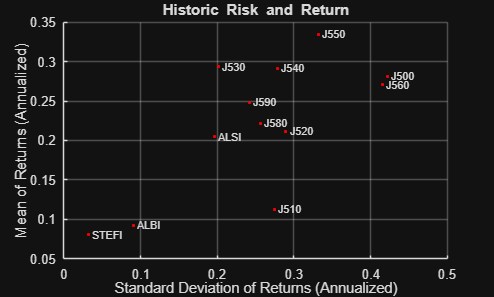

clf; %clear figure
portfolioexamples_plot('Historic Risk and Return', ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Portfolio weigts for 2 Assets

Calculating the Risk-Return trade-off for two-risky assets

Create a new Portfolio objects that incorporates the specified tickers only and estimate the asset moments.

p = Portfolio('AssetList',allDataTable.Properties.VariableNames(tickers));
p = estimateAssetMoments(p,allDataReturnsTable{:,tickers});

Number of rows of weights

rowNum = 60;

Generate a weight vector for 2 assets

Wts = (0:rowNum)/rowNum;
PortWts = [Wts',(1-Wts)'];

#### Risk-Return relationship for 2 Assets

Compute return and risk for each weight vector (How are the returns calculated?) 

In this live script the computation of the portfolio risk and returns is done through the use of MATLAB built-in functions. The calculations are as follows:

Returns

- input - asset means and weights

Risk

- inputs - asset covarince and weights

ret = estimatePortReturn(p, PortWts')

ret =     0.0279
    0.0276
    0.0273
    0.0270
    0.0266
    0.0263
    0.0260
    0.0257
    0.0254
    0.0251
    0.0248
    0.0245
    0.0242
    0.0239
    0.0236


rsk = estimatePortRisk(p,PortWts')

rsk =     0.0957
    0.0948
    0.0940
    0.0931
    0.0923
    0.0915
    0.0907
    0.0899
    0.0891
    0.0884
    0.0876
    0.0869
    0.0862
    0.0855
    0.0849


#### Add an Efficient Frontier

Add risk return curves to plot 

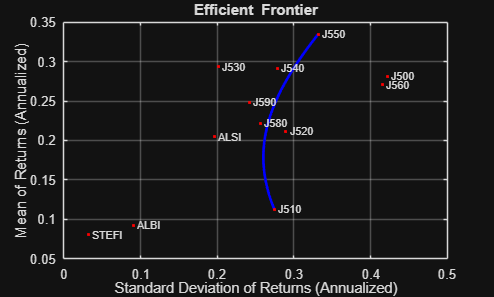

clf;
portfolioexamples_plot('Efficient Frontier', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Visualise the weights 

Plot the control simplex as an inset plot 

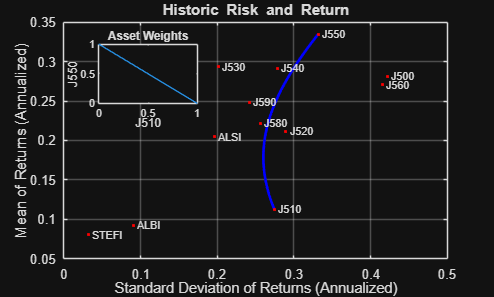

portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
axes('Position',[.2 .65 .2 .2])
box on

plot(PortWts(:,1),PortWts(:,2));
% plot(PortWts)
title('Asset Weights')
xlabel('J510')
ylabel('J550')
hold off

#### The effect of correlations

Calculating the Risk-Return trade-off for two-risky assets

%with different correlation
rho2ij = [1,0.5,0,-0.5,-0.98];

%We use the original annualized variances
s1ij = sqrt(diag(p.AssetCovar));


Compute the portfolio volatility

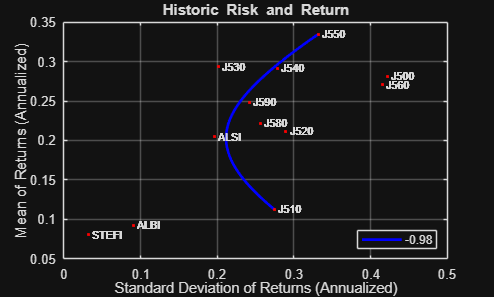

%loop over different correlations

figure;

for j = 1:length(rho2ij)
    %create the family of correlation matrices
    Rho2 = eye(2); %initialise correlations
    Rho2(2,1) = rho2ij(j);
    Rho2(1,2) = Rho2(2,1);%symmetric
    Sigma2 = diag(s1ij) .* Rho2 .* diag(s1ij);
    p.AssetCovar = Sigma2;
 
   %Compute return and risk
   ret = estimatePortReturn(p, PortWts');
   rsk = estimatePortRisk(p,PortWts');

%matrix to plot
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk, ret,{string(rho2ij(j))}}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'}); hold on
end

#### Fully invested portfolio with varying risk aversion 

Plot Efficient frontier by varying risk aversion by solving the risk adjusted return maximisation:


$$\max_{\omega} \left\{ {\mu \omega - \frac{\gamma}{2} \omega \Sigma \omega} \right\} s.t. \omega' {\bf 1} = 1$$


for the vector of portfolio weights $\omega$ where these sum to one. This is done by instead solving: 


$$\min_x \left\{ {\frac{1}{2} x' H x + f'x } \right\} s.t. A x \leq b$$


for an appropriate choice of H, f, A and x. Where we implement the equality constraint as two inequality constraints or use the equality constraint functionality.

%create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,50);

%Fully Invested
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;

Initialise the weights

PortWts = NaN(length(lambda),length(q.AssetMean));

Find the weight vector for each return level using that $H = \Sigma$ (the asset covariance matrix) and that $f = - \lambda \mu $ for the asset returns $\mu$ and the parameter $\lambda$ that selects the return level at which the risk is minimised. 

for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,[],[],q.AEquality,q.bEquality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Compute Portfolio Risk and Return

Compute return and risk for each weight vector

ret = estimatePortReturn(q, PortWts');
rsk = estimatePortRisk(q,PortWts');


Add risk return curves to plot

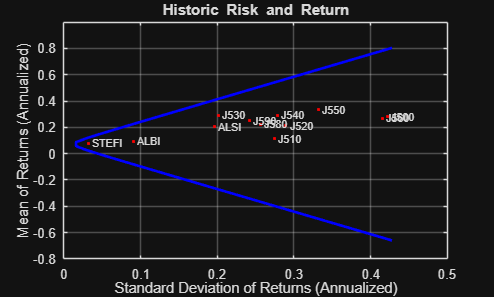

clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Include the no short selling constraint

We again want to solve an optimisation the maximises the risk adjusted returns. However, now we need to include both the full investment constraint: $\sum_i \omega_i = 1$(wihich in vector notation is $\omega' {\bf 1} =1 $and is an equality constraint), and the inequality constraints $\omega_i \geq 0$ (or in vector notation $\omega \geq 0$).

% Create the range of risk aversion parameters
lambda = 6*linspace(-0.5,1,90);

% Fully Invested (equality constraint)
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;

No short-selling (using that $A x \leq b$ we then have that A = - I for the identity marix I, and b = 0)

% No Short-selling (inequality constraint)
q.AInequality = -eye(length(q.AssetMean));
q.bInequality = zeros(length(q.AssetMean),1);

Initialise the weights

PortWts = NaN(length(lambda), length(q.AssetMean));

 Find the weight vector for each return level here 

for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,q.AInequality,q.bInequality,q.AEquality,q.bEquality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Fully invested and no short selling

Compute return and risk for each weight vector

ret = estimatePortReturn(q, PortWts');
rsk = estimatePortRisk(q,PortWts');


Add risk return curves to plot

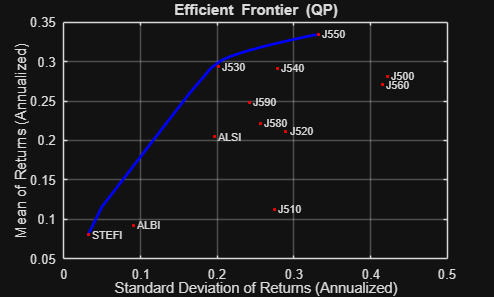

clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Mutual/Pension Fund Efficient Frontier

Plot Efficient frontier by varying risk aversion and only keep positive risk aversion

% Create the range of risk aversion parameters
lambda = 6*linspace(0,1,45);

Fully Invested

% Fully Invested
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;

No short-selling

% No Short-selling
q.AInequality = -eye(length(q.AssetMean));
q.bInequality = zeros(length(q.AssetMean),1);

Initialise the weights

PortWts = NaN(length(lambda), length(q.AssetMean));

 Find the weight vector for each return level

for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,q.AInequality,q.bInequality,q.AEquality,q.bEquality);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Fully invested, no short selling and positive risk-aversion

Compute return and risk for each weight vector

ret = estimatePortReturn(q, PortWts');
rsk = estimatePortRisk(q,PortWts');


Add risk return curves to plot

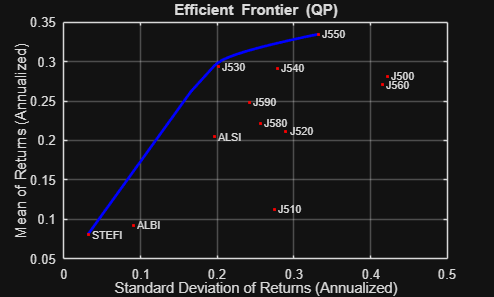

clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

### Load the Data

Clear workspace and load previously prepared data

clc
close all
clear

load('PortfolioTheory.mat')

Define tickers of interest 

Entities = allDataReturnsTable.Properties.VariableNames;

Remove the money market asset (we will compute excess returns!)

Entities = setdiff(Entities, {'STEFI','ALSI'}, 'stable');

Reference out the risk-free asset returns

riskFreeReturns = allDataReturnsTable(:,'STEFI');

Reference out the "market portfolio"

marketPort = allDataReturnsTable(:,'ALSI');

Create a new Porfolio object to incorporate the tickers of interest and estimate the asset moments

r = Portfolio('AssetList',allDataTable.Properties.VariableNames(Entities));
r = estimateAssetMoments(r,allDataReturnsTable{:,Entities}); %BOND + EQTY. INDEX. PORTFOLIO

#### Compute Risk and Return

Compute the Arithmetic mean

Without correcting for missing data (nan)

r.RiskFreeRate = mean(riskFreeReturns{:,:});

Include the missing data

r.RiskFreeRate = mean(riskFreeReturns{:,:},'omitnan');
mktMean = mean(marketPort{:,:},'omitnan');
mktStdDev = std(marketPort{:,:},'omitnan')

mktStdDev = 0.0566

#### Visualise Risk and Return

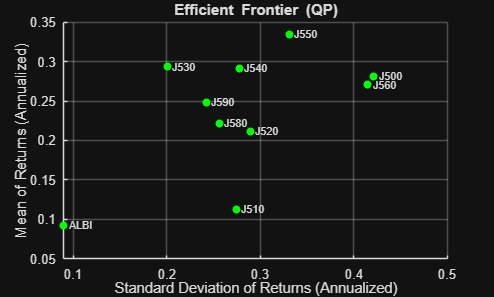

portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'scatter', sqrt(diag(r.AssetCovar)), r.AssetMean, r.AssetList});

#### Compute the Efficient Frontier

Plot Efficient frontier by varying risk aversion 

% create the range of risk aversion parameters
lambda = 6*linspace(0,1,90);

Fully Invested (as inequality constraints)

r.AInequality = ones(2,length(r.AssetMean));
r.bInequality = ones(2,1);

No short-selling

r.AInequality = vertcat(r.AInequality,eye(length(r.AssetMean)));
r.bInequality = [r.bInequality; zeros(length(r.AssetMean),1)];

Initialise the weights

PortWts = NaN(length(lambda), length(r.AssetMean));

 Find the weight vector for each return level ensure that the compounding is correct

for i = 1:length(lambda)
    f = - r.AssetMean * lambda(i); % This moves the solution up along the efficient frontier
    H = r.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,r.AInequality,r.bInequality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Fully invested, no short selling and positive risk-aversion

Compute return and risk for each weight vector

ret = estimatePortReturn(r, PortWts');
rsk = estimatePortRisk(r,PortWts');

Compute the sharpe ratio

SR = ((ret-r.RiskFreeRate) ./ sqrt(rsk)) 

SR =    -0.0025
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Add risk return curves to plot

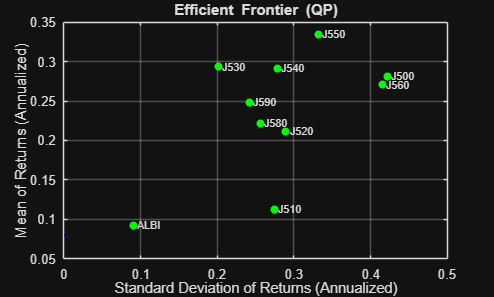

clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk, ret}, ...
	{'scatter', sqrt(diag(r.AssetCovar)), r.AssetMean, r.AssetList});

#### Find the Sharpe Ratio Maximising Portfolio

Find The Sharpe Ratio maximising portfolio

Initial values as fully invested equally weighted portfolio

Ones0 = linspace(1,1,length(r.AssetMean));

%Equally weighted portfolio
Wts0 = Ones0 / length(Ones0);

% unit vector
e = ones(length(Wts0),1); 

%initialise the weights
Wts = NaN(1,length(r.AssetMean));

fn0 = @(x) (-(x.* r.AssetMean' - r.RiskFreeRate)/sqrt(x*r.AssetCovar.*x) );

Fully Invested + Return Target

heq0 = @(x) (x* e - 1); % fully invested
c = @(x) [];
nonlinfcn = @(x)deal(c(x),heq0(x)); %conmbine nonlinear equality and inequality constraints

% Use SQP to solve for the tangency portfolio
options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8)

options =   fmincon options:

   Options used by current Algorithm ('sqp'):
   (Other available algorithms: 'active-set', 'interior-point', 'sqp-legacy', 'trust-region-reflective')

   Set properties:
                    Algorithm: 'sqp'
          OptimalityTolerance: 1.0000e-08

   Default properties:
          ConstraintTolerance: 1.0000e-06
                      Display: 'final'
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
       MaxFunctionEvaluations: '100*numberOfVariables'
                MaxIterations: 400
               ObjectiveLimit: -1.0000e+20
                    OutputFcn: []
                      PlotFcn: []
                 ScaleProblem: 0
    SpecifyConstraintGradient: 0
     SpecifyObjectiveGradient: 0
                StepTolerance: 1.0000e-06
           

soln = fmincon(fn0, Wts0, [],[],[],[],... %target returns
               zeros(length(Wts0),1),...  %no short-selling
               ones(length(Wts0),1),...   %no leverage
               nonlinfcn, options); % fully invested constraint function


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Wts = soln

Wts =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000         0    0.0000    0.0000


#### Fully invested, no short selling and positive risk-aversion

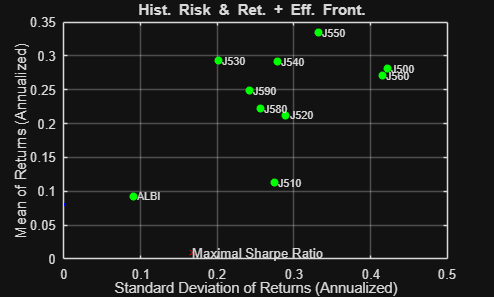

ERetPSR = Wts * r.AssetMean;

% use matrix multiplication to find the risk
ERiskPSR = Wts * r.AssetCovar * Wts';
% add risk return curves to plot

portfolioexamples_plot('Hist. Risk & Ret. + Eff. Front. ', ...
    {'line', rsk, ret}, ...
	{'scatter', sqrt(diag(r.AssetCovar)), r.AssetMean, r.AssetList})
hold on

plot(sqrt(ERetPSR),ERiskPSR,'xr')
text(sqrt(ERetPSR),ERiskPSR,'Maximal Sharpe Ratio')
hold off

#### Compute and Plot the Tangency porfolio

SR0 = ((ERetPSR-r.RiskFreeRate) ./ sqrt(ERiskPSR));
eq = @(x) (r.RiskFreeRate + SR0 * x);
x = linspace(0,0.30,20);

#### Fully invested, no short selling and positive risk-aversion

Plot SML (Security Market Line) 

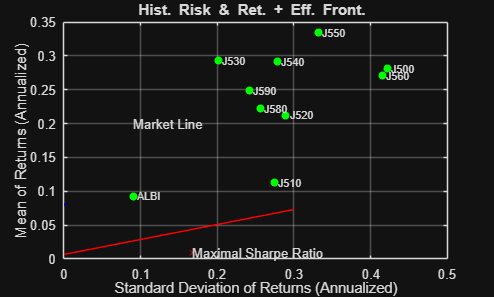

clf; %clear figure
portfolioexamples_plot('Hist. Risk & Ret. + Eff. Front. ', ...
    {'line', rsk, ret},...
	{'scatter', sqrt(diag(r.AssetCovar)), r.AssetMean, r.AssetList})
hold on

plot(sqrt(ERetPSR),ERiskPSR,'xr')
text(sqrt(ERetPSR),ERiskPSR,'Maximal Sharpe Ratio')
hold on

plot(x,eq(x),'r')
text(0.09,0.20,'Market Line')
hold off

#### Visualise the Sharpe Ratio values 

Plot the Sharpe Ratio against risk levels

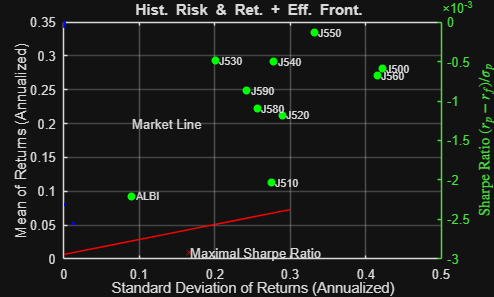

clf; %clear figure
portfolioexamples_plot('Hist. Risk & Ret. + Eff. Front. ', ...
    {'line', rsk, ret},...
	{'scatter', sqrt(diag(r.AssetCovar)), r.AssetMean, r.AssetList})
hold on

plot(sqrt(ERetPSR),ERiskPSR,'xr')
text(sqrt(ERetPSR),ERiskPSR,'Maximal Sharpe Ratio')
hold on

plot(x,eq(x),'r')
text(0.09,0.20,'Market Line')
hold on

%plot the Sharpe Ratio against risk levels
yyaxis right
plot(sqrt(rsk),SR,'.b')
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex')
hold off